% 3.1 From the course website download D_mpg.mat
load ('D_mpg.mat')

% 3.2 Prepare matrix X_tr and y_tr based on Eq. (E1.2).
y = D_mpg(7,:)';
M = length(y);
P = 314;
T = M - P;
X = D_mpg(1:6,:);
Xh = [X; ones(1,M)];
Xh_tr = Xh(:,1:P);
y_tr = y(1:P);

% 3.3 Prepare test data X_te and associated output y_te . 
Xh_te = Xh(:,P+1:M);
y_te = y(P+1:M); 

% 3.4 Prepare MATLAB code to compute optimal parameter w^* for the model in
% (E1.1) using Eq (E1.3)
w = pinv(Xh_tr')*y_tr;

% 3.5 Apply the optimized model to the train and test data respectively, 
% and evaluate the root-mean-squared error
rmse_train = RMSE(w, Xh_tr, y_tr,314)

rmse_train = 3.5668

rmse_test = RMSE(w, Xh_te, y_te,78)

rmse_test = 2.6662

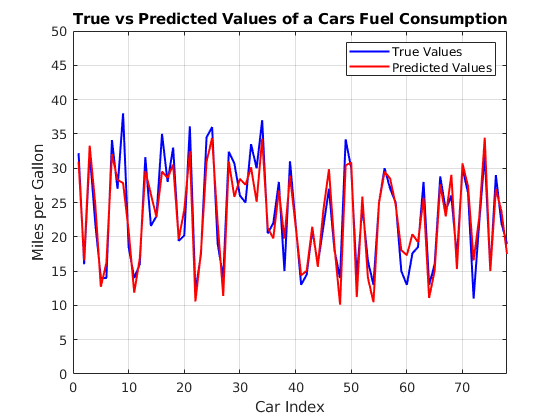

% 3.6 For comparison, in a single figure, plot the "ground truth” output 
% y_te as a curve colored in blue and its prediction
% as the second curve colored in red. 
w_padded_y_te = repmat(w,1,78);
y_te_prediction = dot(w_padded_y_te, Xh_te, 1); 

set(gca, 'fontsize', 14)
ind = [1:78];
plot(ind, y_te, 'b-', ind, y_te_prediction, 'r-', 'LineWidth', 1.5)
grid on; 
axis([0 78 0 50])
xlabel('Car Index')
ylabel('Miles per Gallon')
title('True vs Predicted Values of a Cars Fuel Consumption')
legend('True Values', 'Predicted Values')

% Bonus Task 
epsilon = 10^-6; % Setting epsilon value 
w_0 = [0.8239 0.7633 0.8131 0.6941 0.4657 0.9926 0.8673]'; 
[w_bonus,~,~] = grad_desc_Lab1('L2_loss','grad_L2_loss',w_0,epsilon, Xh_tr, y_tr);

solution:


w =     0.7937
    0.0000
    0.0116
   -0.0086
    0.3896
    0.4808
    0.8598


objective function at solution point:


fs = 14.2754

number of iterations performed:


k = 38297

rmse_train_bonus = RMSE(w_bonus, Xh_tr, y_tr,314)

rmse_train_bonus = 3.7783

rmse_test_bonus = RMSE(w_bonus, Xh_te, y_te,78)

rmse_test_bonus = 2.9793

function r = RMSE(w,x,y,n)
% w is the vector that includes the optimal weight and bias, x is a
% collection of data points (with parameters) for which we want to predict
% something, y is a collection of the true prediction values, n is the
% number of samples in the dataset 

    w_padded = repmat(w,1,n); % number of columns corresponds to the number of testing samples 
    wTx = dot(w_padded, x, 1); % returns a vector where each entry is the dot product of a testing sample and w
    
    sum_input = (wTx'-y).^2; % subtracting the true value of y from the estimated value of y and squaring each term
    norm_sum = sum(sum_input)/n; % sum of each term in sum_input, divided by the total number of terms 
    
    r = sqrt(norm_sum); % Root mean squared error 
end

function output = L2_loss(w, X, y)
% Following equation 1.25 in the Chapter 1 slides 
    P = length(y);
    w_padded = repmat(w,1,P);% number of columns corresponds to the number of testing samples 
    wTx = dot(w_padded, X, 1); % returns a vector where each entry is the dot product of a testing sample and w
    
    sum_input = (wTx'-y).^2; % subtracting the true value of y from the estimated value of y and squaring each term
    output = sum(sum_input)/P; % sum of each term in sum_input, divided by the total number of terms 
end 

function output = grad_L2_loss(w, X, y)
% The gradient of the L2 loss function is stated on page 58 of the Chapter 1 lecture slides, I am replicating that in this function.  
    P =length(y); 
    
    Q = zeros(7,7); % initailaizing 
    q = zeros(7,1); % initializing
    
    for i =1:P % Using a for loop to ensure I am multiplying the correct values 
        q = q + (y(i)*X(:,i)); % Summing values for q
        Q = Q + (X(:,i)*X(:,i)'); % Summing values for Q 
    end
     
   q = q/P; % Normalizing 
   Q = Q/P; % Normalizing 
   
   output = 2*Q*w-2*q; % See page 58, Ch1 slides
end


function [w,fs,k] = grad_desc_Lab1(fname,gname,x0,epsi, X, y) % Function Provided
format compact
format long
k = 1;
xk = x0;
gk = feval(gname, xk, X, y);
dk = -gk;
ak = bt_lsearch_Lab1(xk,dk,fname,gname, X, y);
adk = ak*dk;
er = norm(adk);
while er >= epsi,
  xk = xk + adk;
  gk = feval(gname,xk, X, y);
  dk = -gk;
  ak = bt_lsearch_Lab1(xk,dk,fname,gname, X, y);
  adk = ak*dk;
  er = norm(adk);
  k = k + 1;
end
disp('solution:')
w = xk + adk
disp('objective function at solution point:')
fs = feval(fname,w, X, y)
format short
disp('number of iterations performed:')
k
end

function a = bt_lsearch_Lab1(x,d,fname,gname,p1,p2) % Function Provided
rho = 0.1;
gma = 0.5;
x = x(:);
d = d(:);
a = 1;
xw = x + a*d;
parameterstring ='';
if nargin == 5
   if ischar(p1)
      eval([p1 ';']);
   else
      parameterstring = ',p1';
   end
end
if nargin == 6
   if ischar(p1)
      eval([p1 ';']);
   else
      parameterstring = ',p1';
   end
   if ischar(p2)
      eval([p2 ';']);
   else
      parameterstring = ',p1,p2';
   end
end

eval(['f0 = ' fname '(x' parameterstring ');']);
eval(['g0 = ' gname '(x' parameterstring ');']);
eval(['f1 = ' fname '(xw' parameterstring ');']);

t0 = g0'*d;
f2 = f0 + rho*a*t0;
er = f1 - f2;
while er > 0
     a = gma*a;
     xw = x + a*d;
     eval(['f1 = ' fname '(xw' parameterstring ');']);
     f2 = f0 + rho*a*t0;
     er = f1 - f2;
end
end